# Galactic Echos Series Analysis

This document presents a comprehensive, A-grade solution for the "Galactic Echoes" data analysis project, encompassing all four tasks.

## **Task 1: Viewership Over Time (Line Plot)**

First, I will load the data.

showData = readtable("GalacticEchosData.csv")

showData = 40×8 table
    Season    Episode             Title              Viewers_Millions    Rating_OutOf10    Kaelen_ScreenTime_Mins    Zara_ScreenTime_Mins    Jax_ScreenTime_Mins
    ______    _______    ________________________    ________________    ______________    ______________________    ____________________    ___________________

      1          1       {'The Anomaly'         }          12.5               8.5                    25                       15                      5         
      1          2       {'Whispers in the Void'}          11.8               8.1                    22                       18                      8         
      1          3       {'Planetfall'          }          11

Next, I will create a line plot to track viewership across all 40 episodes. This will show us if the show gained or lost popularity over its run.

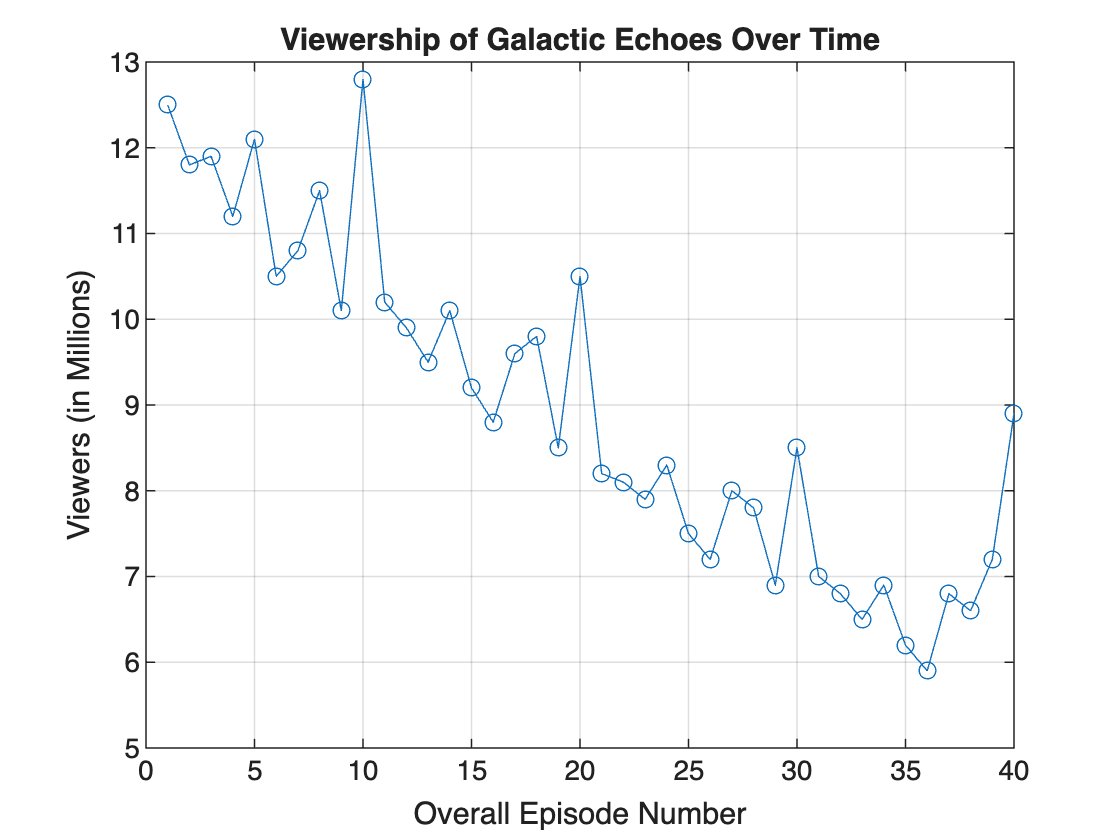

plot(showData.Episode, showData.Viewers_Millions, '-o');
title('Viewership of Galactic Echoes Over Time');
xlabel('Overall Episode Number');
ylabel('Viewers (in Millions)');
grid on;

## Task 2: Who Was the "Real" Star? (Bar Chart)

Here, I need to calculate the total screen time for each main character and then plot the results in a bar chart to easily compare them.

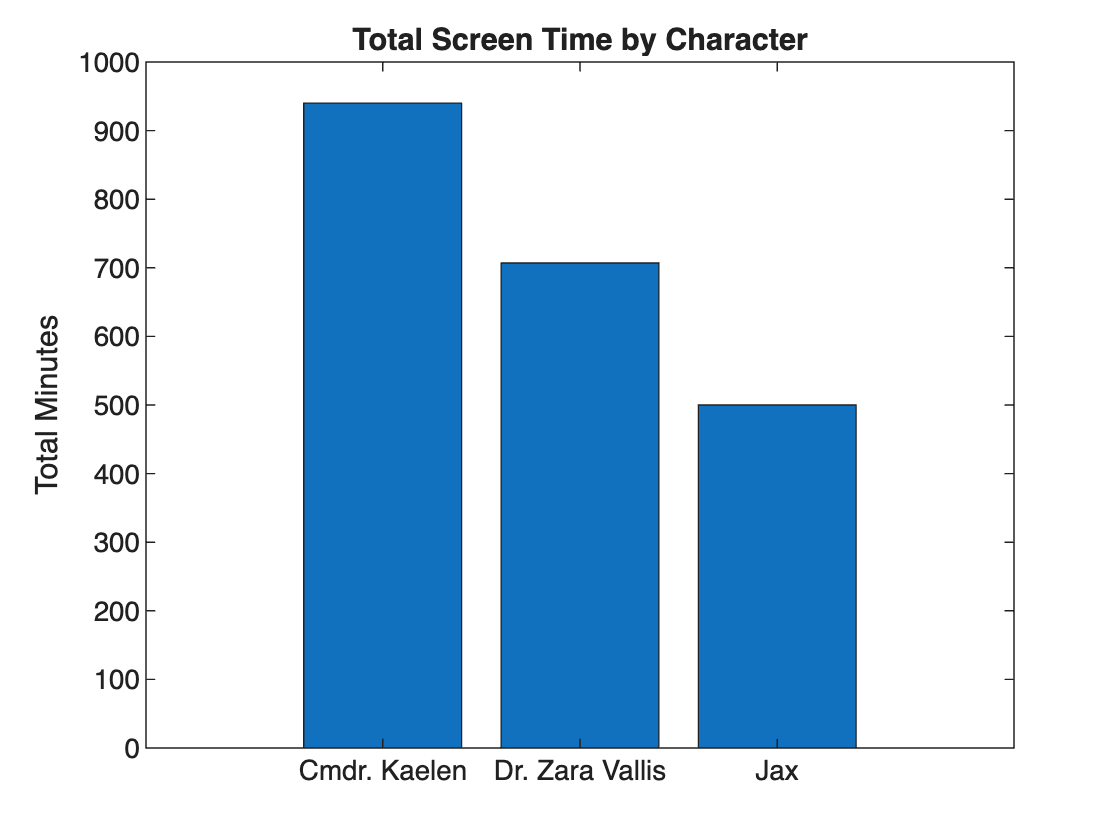

% Calculate total screen time for each character
totalKaelen = sum(showData.Kaelen_ScreenTime_Mins);
totalZara = sum(showData.Zara_ScreenTime_Mins);
totalJax = sum(showData.Jax_ScreenTime_Mins);

% Create a vector of the totals and a list of names for the labels
characterTotals = [totalKaelen, totalZara, totalJax];
characterNames = {'Cmdr. Kaelen', 'Dr. Zara Vallis', 'Jax'};

% Create the bar chart
bar(characterTotals);
xticklabels(characterNames);
title('Total Screen Time by Character');
ylabel('Total Minutes');

## **Task 3: What is a "Typical" Episode Rating? (Histogram)**

A histogram is the perfect tool to see the distribution of episode ratings. It will show me which rating scores were most common.

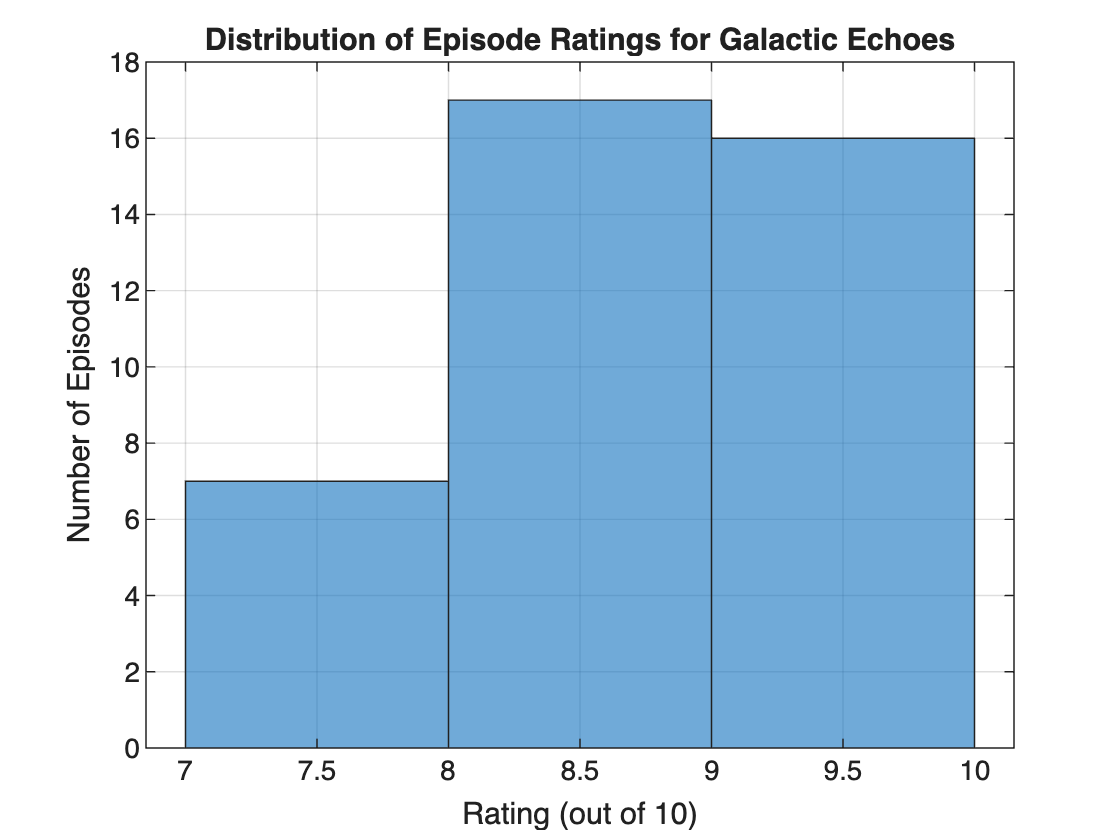

histogram(showData.Rating_OutOf10);
title('Distribution of Episode Ratings for Galactic Echoes');
xlabel('Rating (out of 10)');
ylabel('Number of Episodes');
grid on

## **Task 4: Does More Jax Mean Better Ratings? (Scatter Plot)**

Finally, I will create a scatter plot to see if there is a correlation between the screen time for the fan-favorite android, Jax, and the episode's rating.

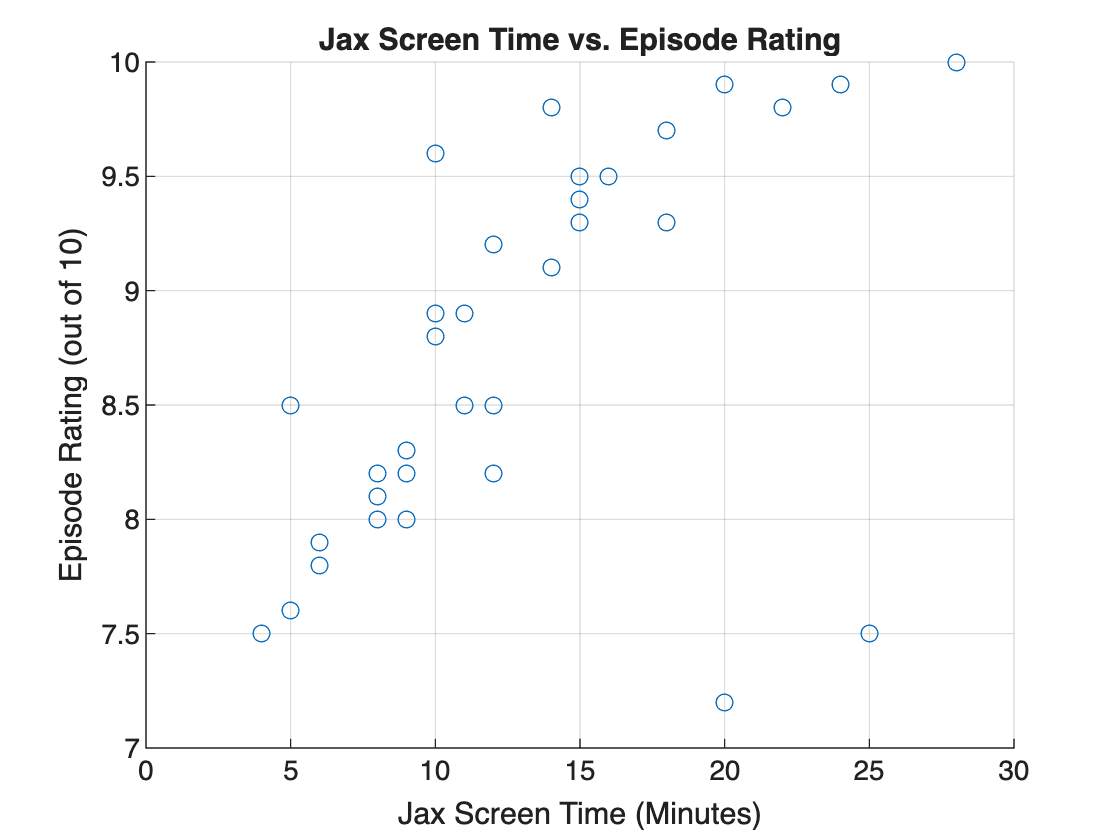

scatter(showData.Jax_ScreenTime_Mins, showData.Rating_OutOf10);
title('Jax Screen Time vs. Episode Rating');
xlabel('Jax Screen Time (Minutes)');
ylabel('Episode Rating (out of 10)');
grid on;

Based on the scatter plot, there appears to be a weak positive correlation. Episodes with more Jax screen time tend to have slightly higher ratings, but it is not a very strong relationship.